# Group Project: Virtual MRI Scanner

# Phantom Creation

% Generates a phantom image
function matrix = generatePhantoms(size, ellipses, addRectangle)
    matrix = phantom(ellipses, size);

    % Adds a rectangle to the matrix by defining a rectangular region in
    % which the signal intensity for pixels in this region is set appropriately
    if addRectangle == true
        [x, y] = deal(size);
        midX = x / 2;
        deltaX = x / 15;
        leftXBoundary = midX - deltaX;
        rightXBoundary= midX + deltaX;
    
        midY = y / 2;
        deltaY = y / 3.5;
        topYBoundary = midY - deltaY;
        bottomYBoundary= midY + deltaY;

        for i=1:x
            for j=1:y
                % Ensure current coordinate is within the rectangle's boundaries
                if (j >= leftXBoundary) && (j <= rightXBoundary) && (i >= topYBoundary) && (i <= bottomYBoundary)
                    matrix(i, j) = 1;
                end
            end
        end
    end
    %figure, imshow(matrix)
    figure;
    imagesc(matrix);
    colormap("gray");
    colorbar;
end

phantomOne = [0.5 0.75 0.75 0 0 0];   % Outer circle ellipse (rectangle region added below)

phantomTwo = [0.5 0.75  0.75   0    0 0 % Outer circle ellipse
              1.0 0.20  0.20   0.5  0 0 % Right most inner circle ellipse
              1.0 0.15  0.15   0.1  0 0 % Second from right circle ellipse
              1.0 0.10  0.10  -0.2  0 0 % Third from right circle ellipse
              1.0 0.05  0.05  -0.4  0 0 % Fourth from right circle ellipse
              1.0 0.025 0.025 -0.52 0 0 % Left most inner circle ellipse
             ];

% Set size
N = 256; % GUI MODIFIED VARIABLE

% Generate phantoms
disp("Phantom One")

Phantom One


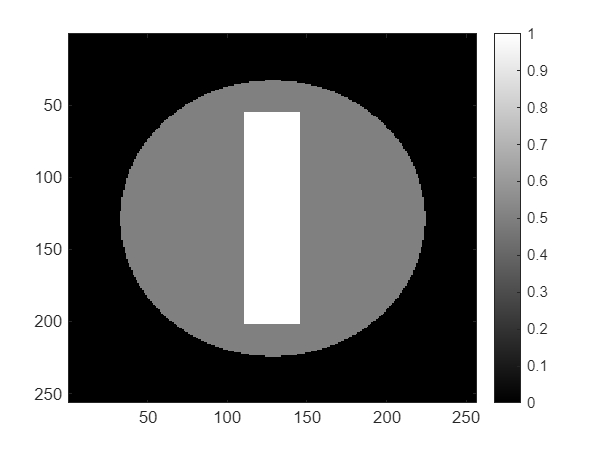

matrixOne = generatePhantoms(N, phantomOne, true);


disp("Phantom Two")

Phantom Two


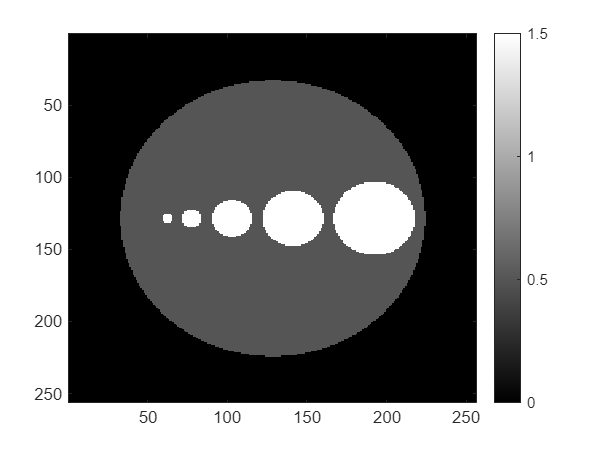

matrixTwo = generatePhantoms(N, phantomTwo, false);

# K-Space

Phantom 1 Forward FFT

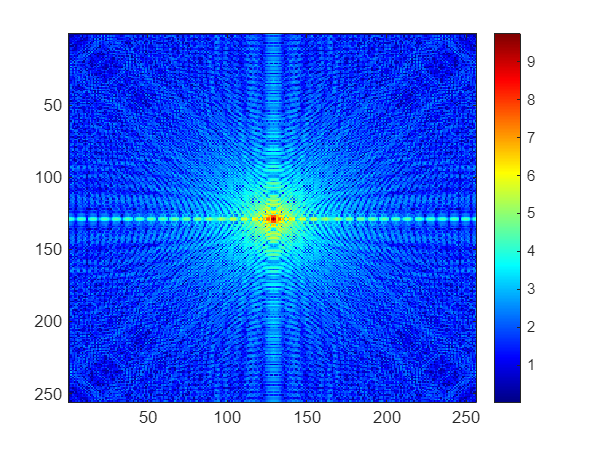

% Generate and show the k-space of a phantom
% FIX ME: Need to add another variable to keep track of user input
% parameters to show as sgtitle(parametersHere); or as a legend box
% (whatever looks better) per section [7]
function kspace = fftTransform(matrix, direction, text)
    if direction == "forward"
        color = "jet";
        fprintf(text);
        kspace = fft2(matrix);
        imageArray = log(1 + abs(fftshift(kspace)));
    else
        color = "gray";
        fprintf(text);
        kspace = ifft2(matrix);
        imageArray = abs(kspace);
    end

    figure;
    imagesc(imageArray);
    colormap(color);
    colorbar;
end

% Get FFT images for both phantoms
fftOne = fftTransform(matrixOne, "forward", "Phantom 1 Forward FFT");

Phantom 2 Forward FFT 

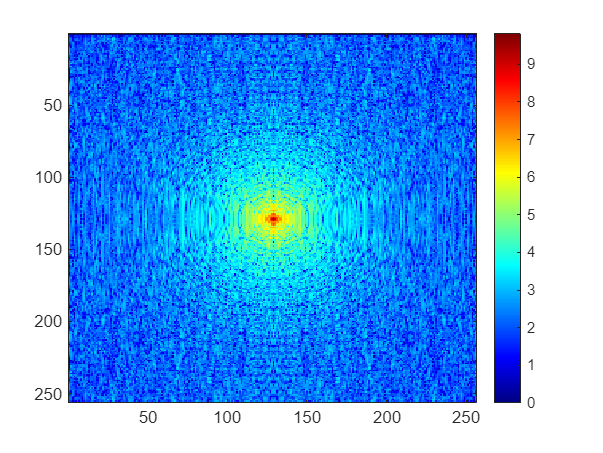

fftTwo = fftTransform(matrixTwo, "forward", "Phantom 2 Forward FFT ");

Phantom 1 Inverse FFT

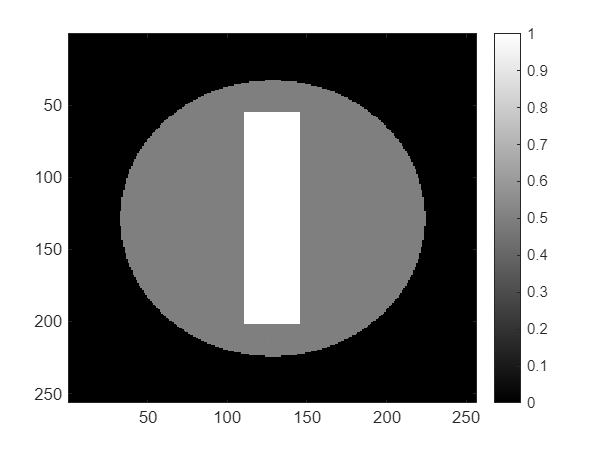


% Run FFT inverse to show that it all works correctly
fftOneReverse = fftTransform(fftOne, "inverse", "Phantom 1 Inverse FFT");

Phantom 2 Inverse FFT

fftTwoReverse = fftTransform(fftTwo, "inverse", "Phantom 2 Inverse FFT");

# Cartesian Acquisition Trajectory

% Cartesian Acquisition Trajectory which returns final image matrix given user parameters
function reconstruction = cartesianSample(matrix, width, pointDensity, lineDensity, swap)
    [rows,cols] = size(matrix);
    reconstruction = [];
    if swap == true
        rowSpacing   = ceil(cols / pointDensity);
        pointSpacing = ceil(rows / lineDensity);
    else
        rowSpacing   = ceil(rows / lineDensity);
        pointSpacing = ceil(cols / pointDensity);
    end

    for i=1:rowSpacing:width
        row = [];
        for j=1:pointSpacing:width

            if swap == true
                point = matrix(j,i);
            else
                point = matrix(i,j);
            end
            row = [row, point];
        end
        reconstruction = [reconstruction; row];
    end
end

Cartesian - Phantom 1 Inverse FFT

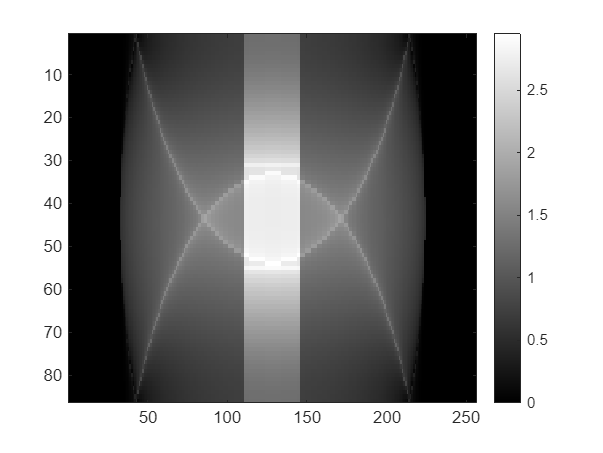

% This must be modified to work with the GUI to set applicable parameters
% The following are variables to be set via the GUI:
matrixWidth                    = 256; % int GUI MODIFIED VARIABLE (CANNOT BE LARGER THAN N)
linePointDensity               = 300; % int GUI MODIFIED VARIABLE
horizontalLineDensity          = 125; % int GUI MODIFIED VARIABLE
swapHorizontalAndVerticalLines = false; % boolean GUI MODIFIED VARIABLE

% Reconstruct both phantoms according to user parameters
reconstructionOneCartesian = cartesianSample(fftOne, matrixWidth, linePointDensity, horizontalLineDensity, swapHorizontalAndVerticalLines);
postFFTOneCartesian = fftTransform(reconstructionOneCartesian, "inverse", "Cartesian - Phantom 1 Inverse FFT");

Cartesian - Phantom 2 Inverse FFT

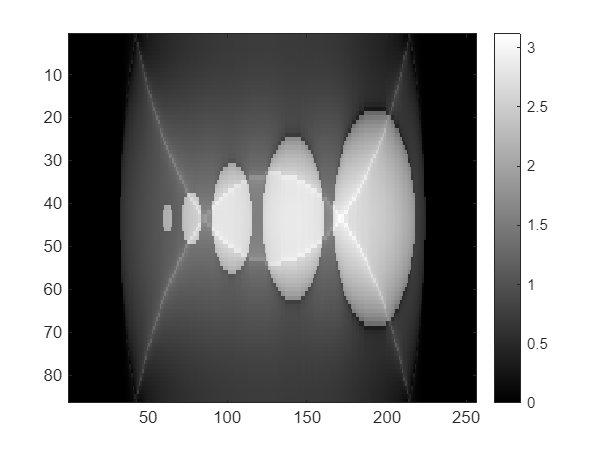


reconstructionTwoCartesian = cartesianSample(fftTwo, matrixWidth, linePointDensity, horizontalLineDensity, swapHorizontalAndVerticalLines);
postFFTTwoCartesian = fftTransform(reconstructionTwoCartesian, "inverse", "Cartesian - Phantom 2 Inverse FFT");

# Radial Acquisition Trajectory

% Radial Acquisition Trajectory which returns final image matrix given
function reconstruction = radialSample(kspace, numRadialLines, numPointsPerLine)
    [rows, cols] = size(kspace);
    centerX = rows / 2;
    centerY = cols / 2;
    reconstruction = zeros(rows, cols);

    % Calculate the angle between each radial line
    angleIncrement = 2 * pi / numRadialLines;

    for n = 0:numRadialLines-1
        angle = n * angleIncrement;
        for p = 1:numPointsPerLine
            % Calculate the coordinates of the point on the radial line
            x = round(centerX + (p - numPointsPerLine/2) * cos(angle));
            y = round(centerY + (p - numPointsPerLine/2) * sin(angle));

            % Ensure the coordinates are within the grid boundaries
            if x > 0 && x <= rows && y > 0 && y <= cols
                reconstruction(x, y) = kspace(x, y);
            end
        end
    end
end

Radial - Phantom 1 Inverse FFT

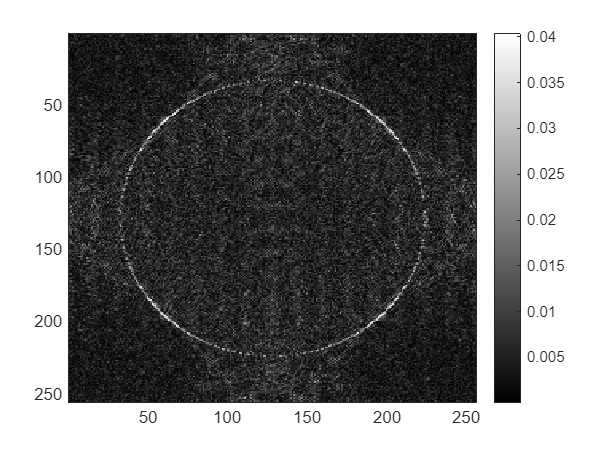

% This must be modified to work with the GUI to set applicable parameters
% The following are variables to be set via the GUI:
numRadialLines   = 50;  % int GUI MODIFIED VARIABLE
numPointsPerLine = 256; % int GUI MODIFIED VARIABLE

% Reconstruct both phantoms using radial sampling
reconstructionOneRadial = radialSample(fftOne, numRadialLines, numPointsPerLine);
postFFTOneRadial = fftTransform(reconstructionOneRadial, "inverse", "Radial - Phantom 1 Inverse FFT");

Radial - Phantom 2 Inverse FFT

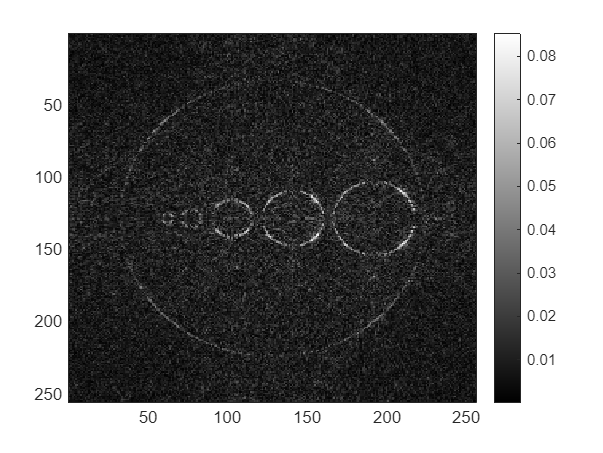


reconstructionTwoRadial = radialSample(fftTwo, numRadialLines, numPointsPerLine);
postFFTTwoRadial = fftTransform(reconstructionTwoRadial, "inverse", "Radial - Phantom 2 Inverse FFT");

# Image Analysis

% Signal Intensity and Contrast
% Return if point is out of matrix boundary
function result = isOutOfBounds(point, size)
    x = point(1);
    y = point(2);

    result = (x < 1) || (y < 1) || (x > size) || (y > size);
end

% Return if point is out of region boundary
function result = isOutOfRegion(center, point, radius)
    x = center(1);
    y = center(2);

    x1 = point(1);
    y1 = point(2);

    distance = sqrt((x - x1)^2 + (y - y1)^2);
    result = distance > radius;
end

% To calculate SI difference of two regions, we first get each region's average SI
function average = calculateAverageSignalIntensityOfRegion(matrix, radius, position)
    dimensions = size(matrix);
    length = dimensions(1);
    x = position(1);
    y = position(2);
    
    % Box containing region
    leftBoundary   = x - radius;
    rightBoundary  = x + radius;
    topBoundary    = y - radius;
    bottomBoundary = y + radius;

    % Running sum to calculate average
    sum = 0;
    count = 0;

    % Get SI for all points within the boundary to later calculate the region's average SI
    for i=leftBoundary:rightBoundary
        for j=topBoundary:bottomBoundary
            point = [i, j];
            % Ensure point is within matrix and region boundaries
            if (isOutOfRegion(position, point, radius) || isOutOfBounds(point, length))
                continue;
            end

            % Increment sum and count to average later (uses abs() to get
            % magnitude of signal intensity, especially for when the matrix
            % has complex numbers
            sum = sum + abs(matrix(i, j));
            count = count + 1;
        end
    end

    average = sum / count;
end

% Returns the difference of SI of two regions of given radius for a given matrix
function difference = signalIntensityDifference(matrix, radius, positionOne, positionTwo)
    averageOfRegionOne = calculateAverageSignalIntensityOfRegion(matrix, radius, positionOne);
    averageOfRegionTwo = calculateAverageSignalIntensityOfRegion(matrix, radius, positionTwo);

    % Calculate difference
    if averageOfRegionOne > averageOfRegionTwo
        difference = averageOfRegionOne - averageOfRegionTwo;
    else
        difference = averageOfRegionTwo - averageOfRegionOne;
    end
end

% Calculates the difference of SI averages between 2 regions of a matrix
testDifference = signalIntensityDifference(matrixOne, 50, [0, 0], [100, 100])

testDifference = 0.6747

testDifferenceCartesian = signalIntensityDifference(postFFTOneCartesian, 50, [0, 0], [100, 100])

testDifferenceCartesian = 0.7067

testDifferenceRadial = signalIntensityDifference(postFFTOneRadial, 50, [0, 0], [100, 100])

testDifferenceRadial = 0.0023


% Signal Intensity Profiles 